% voltage_reset_optionB_demo.m
% Demonstrate per-neuron fractional spike times and Option B split update + LSTI filters
clear; clc;

%% ---- Params (mirror main script) ----
dt     = single(1e-3);
tau_u  = single(50e-3);
tau_w  = single(500e-3);

E_L    = single(-70);
V_th   = single(-50);
V_reset= single(-65);
V_floor= single(inf);

a_eff  = single(0.00);
b_param= single(0.2);

alpha  = exp(-dt/tau_u);
beta   = exp(-dt/tau_w);

tau_rise = single(2e-3);
tau_decay= single(50e-3);
gamma_sr = exp(-dt/tau_rise);
gamma_sd = exp(-dt/tau_decay);
spike_jump_sr = -log(max(gamma_sr, realmin('single'))) / dt;

T    = single(0.2);
K    = round(T/dt);

%% ---- Setup two neurons with slightly different effective drive/slopes ----
N = 2;
u  = single([ -50.1; -50.1 ]);  % start near threshold (mV)
w  = single([ 0.0;    0.0  ]);
x_syn = single([0;0]); r = single([0;0]);

% Constant "input" (mV-equivalent). Make n1 cross earlier than n2.
I_tot = single([22.0; 21.8]);   % tweak values to ensure both cross within a step

% Loggers
U_pre  = zeros(N,K,'single'); U_hat = zeros(N,K,'single');
Rho    = zeros(N,K,'single'); Spk = false(N,K);
U_star = zeros(N,K,'single'); U_post = zeros(N,K,'single');
W_log  = zeros(N,K,'single');
R_log  = zeros(N,K,'single');

%% ---- Vectorised helpers ----
advance_frac = @(gamma,f) exp( f .* log(max(gamma, realmin('single'))) );

for k = 1:K
    % Predict u_hat for rho detection
    u_pre = u;
    u_hat = E_L + alpha.*(u_pre - E_L) + (1-alpha).*(I_tot - w);
    spike = (u_hat >= V_th);

    % rho per neuron
    u_diff = u_hat - u_pre;
    den    = max(u_diff, realmin('single'));
    rho    = zeros(N,1,'single');
    idx    = spike & (u_diff > 0);
    rho(idx) = (V_th - u_pre(idx)) ./ den(idx);
    rho = min(max(rho, single(0)), single(1));
    rho(~isfinite(rho)) = single(0);

    % Pre/post leaks
    a_pre  = advance_frac(alpha,  rho);
    b_pre  = advance_frac(beta,   rho);
    a_post = advance_frac(alpha,  1-rho);
    b_post = advance_frac(beta,   1-rho);

    % (1) pre to t*
    u_star = E_L + a_pre.*(u_pre - E_L) + (1-a_pre).*(I_tot - w);
    w      = b_pre.*w + (1-b_pre).*( a_eff.*(u_star - E_L) );

    % (2) instantaneous spike/reset at t*
    if any(spike)
        u_star(spike) = V_reset;
        w(spike)      = w(spike) + b_param;
    end

    % (3) post to t_{k+1}
    u = E_L + a_post.*(u_star - E_L) + (1-a_post).*(I_tot - w);
    w = b_post.*w + (1-b_post).*( a_eff.*(u - E_L) );
    u = max(u, E_L - V_floor);

    % ---- LSTI-consistent cascade (per neuron) ----
    % pre segment
    gsr_pre  = advance_frac(gamma_sr, rho);
    gsd_pre  = advance_frac(gamma_sd, rho);
    x_syn    = gsr_pre .* x_syn;                  % z_const = 0
    r        = gsd_pre .* r + (1 - gsd_pre) .* x_syn;
    % spike jump
    if any(spike)
        x_syn(spike) = x_syn(spike) + spike_jump_sr;
    end
    % post segment
    gsr_post = advance_frac(gamma_sr, 1 - rho);
    gsd_post = advance_frac(gamma_sd, 1 - rho);
    x_syn    = gsr_post .* x_syn;
    r        = gsd_post .* r + (1 - gsd_post) .* x_syn;

    % Logs
    U_pre(:,k)   = u_pre;
    U_hat(:,k)   = u_hat;
    Rho(:,k)     = rho;
    Spk(:,k)     = spike;
    U_star(:,k)  = u_star;
    U_post(:,k)  = u;
    W_log(:,k)   = w;
    R_log(:,k)   = r;
end

%% ---- Print a single step where both spike to see rhos and post values ----
ks = find(all(Spk,1), 1, 'first');
if ~isempty(ks)
    fprintf('First simultaneous-spike step: k=%d\n', ks);
    for n=1:N
        fprintf('  neuron %d: rho=%.4f  u_pre=%.2f  u_hat=%.2f  u_post=%.2f\n', ...
            n, Rho(n,ks), U_pre(n,ks), U_hat(n,ks), U_post(n,ks));
    end
else
    fprintf('No step with simultaneous spikes; showing first spike per neuron instead.\n');
    for n=1:N
        kk = find(Spk(n,:),1);
        if ~isempty(kk)
            fprintf('  neuron %d: (first spike k=%d) rho=%.4f  u_pre=%.2f  u_hat=%.2f  u_post=%.2f\n', ...
                n, kk, Rho(n,kk), U_pre(n,kk), U_hat(n,kk), U_post(n,kk));
        end
    end
end

First simultaneous-spike step: k=3


  neuron 1: rho=0.4419  u_pre=-50.02  u_hat=-49.98  u_post=-64.81
  neuron 2: rho=0.7055  u_pre=-50.03  u_hat=-49.99  u_post=-64.90


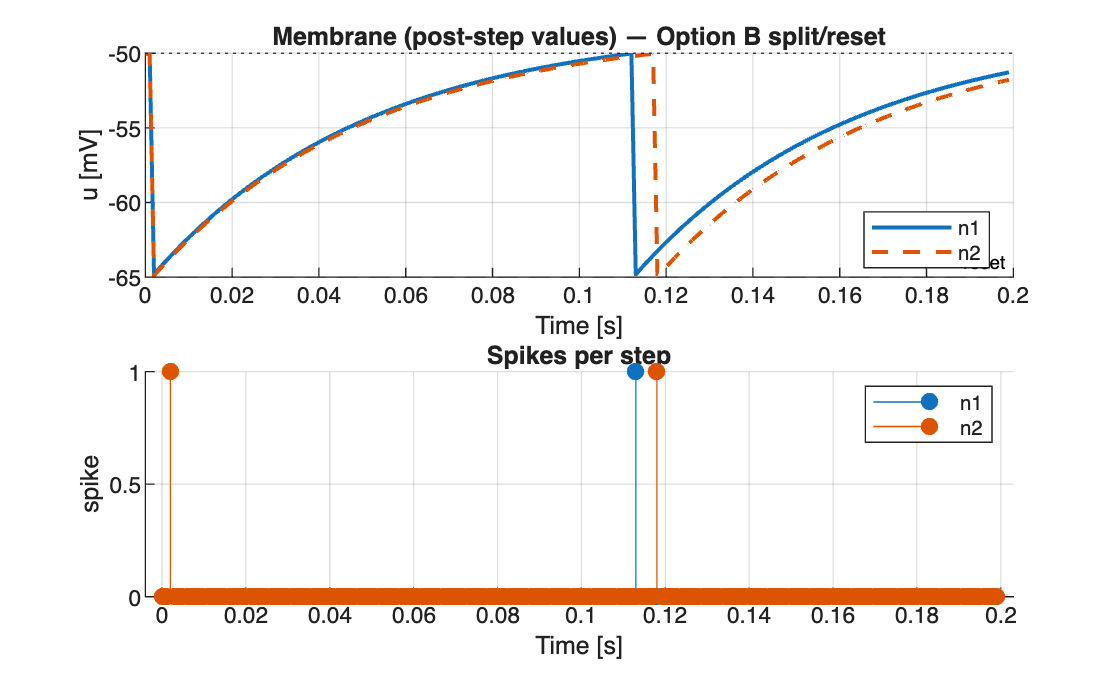


%% ---- Plots ----
t = (0:K-1)*double(dt);

figure; 
subplot(2,1,1); hold on;
plot(t, double(U_post(1,:)),'-','LineWidth',1.5);
plot(t, double(U_post(2,:)),'--','LineWidth',1.5);
yline(double(V_th),'k:','V_{th}');
yline(double(V_reset),'k--','V_{reset}');
xlabel('Time [s]'); ylabel('u [mV]');
title('Membrane (post-step values) — Option B split/reset');
legend('n1','n2','Location','best'); grid on;

subplot(2,1,2); hold on;
stem(t, double(Spk(1,:)),'filled');
stem(t, double(Spk(2,:)),'filled');
xlabel('Time [s]'); ylabel('spike');
title('Spikes per step'); grid on; legend('n1','n2');

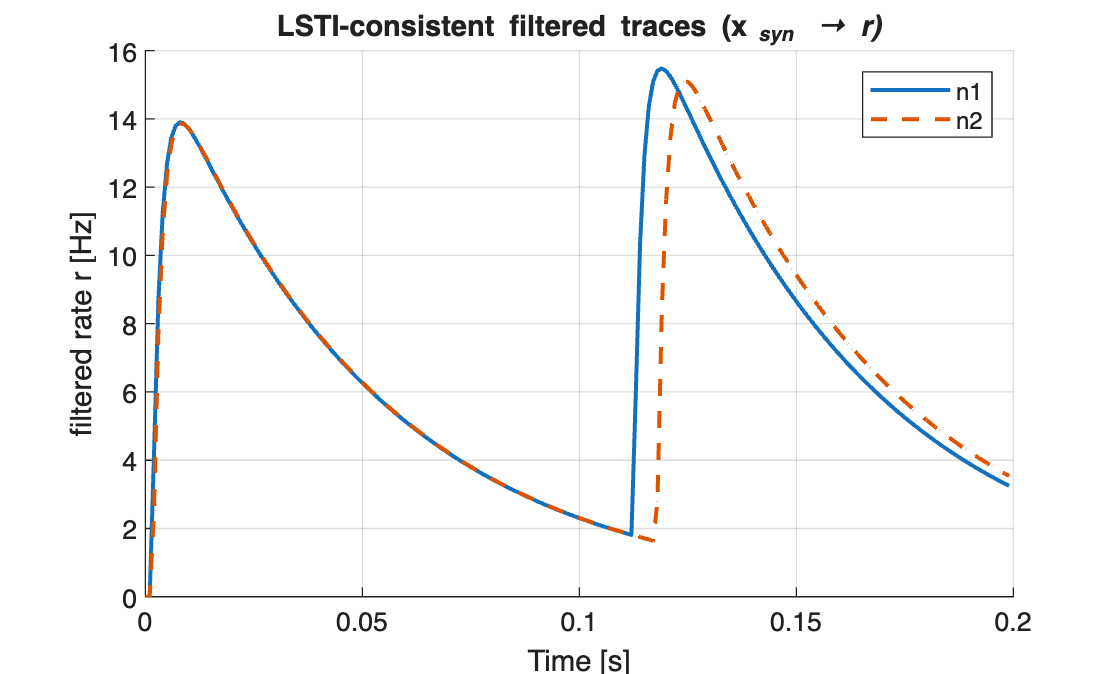


figure; hold on;
plot(t, double(R_log(1,:)),'-','LineWidth',1.5);
plot(t, double(R_log(2,:)),'--','LineWidth',1.5);
xlabel('Time [s]'); ylabel('filtered rate r [Hz]');
title('LSTI-consistent filtered traces (x_{\it syn} \rightarrow r)');
legend('n1','n2'); grid on;